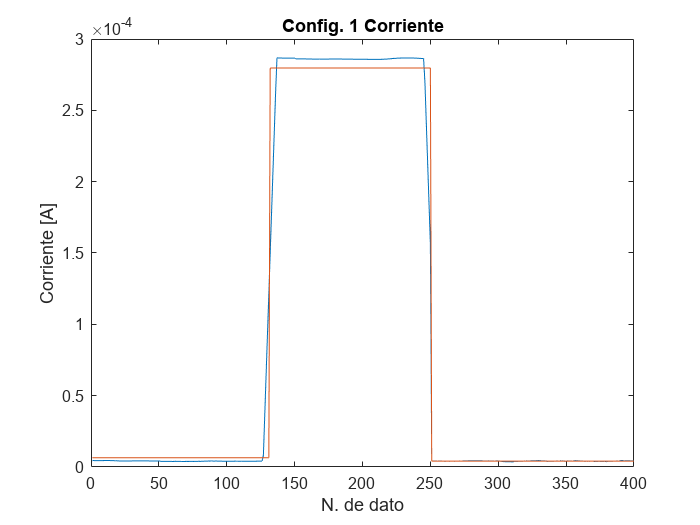

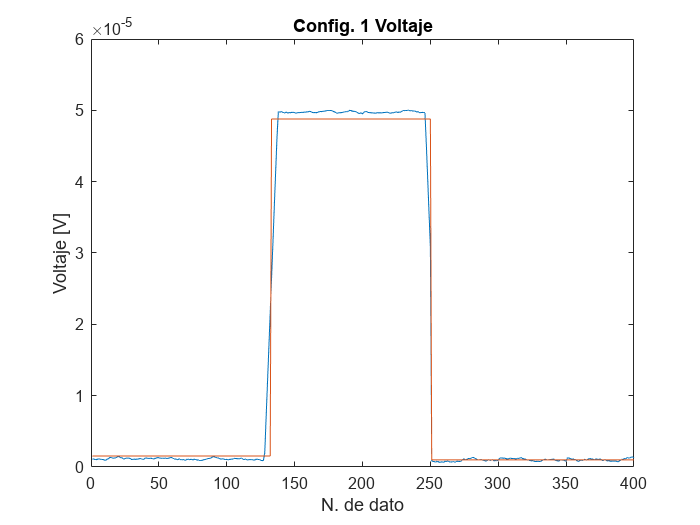

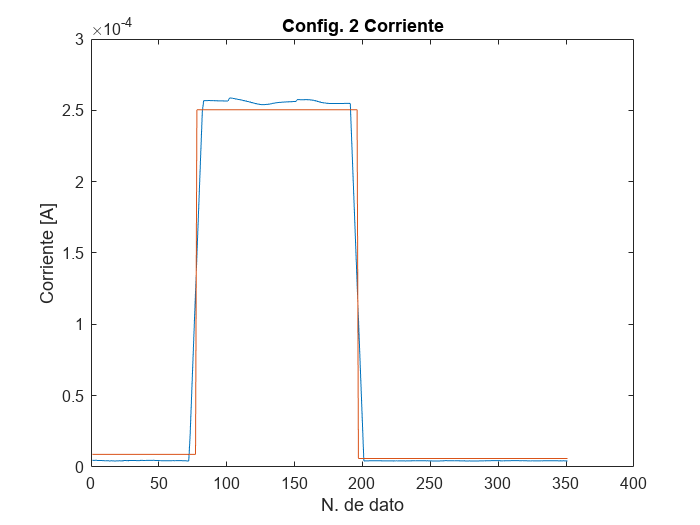

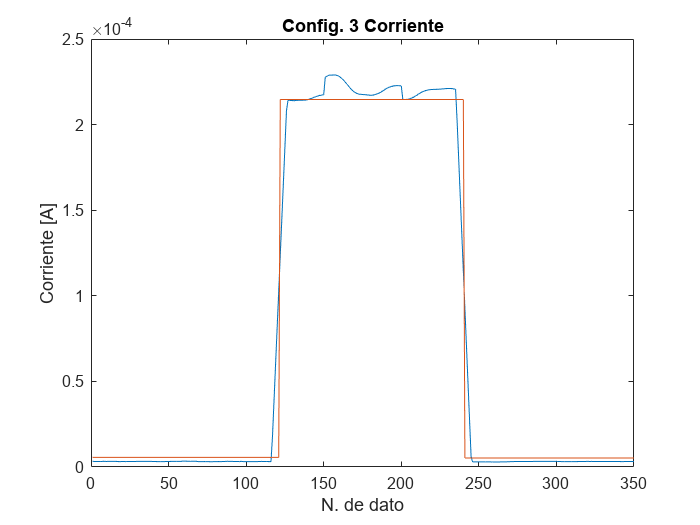

format shortEng

% Cargar la data
dataTable = readtable('datos.txt');
Mdata = table2array(dataTable);

% Espesores de las muestras en cm
espesor_con = 0.0023;
espesor_sin = 0.0028;

% Cte. Van Der Pauw
P = pi * log(2);


% Promedios
if ~exist('IMG', 'dir')
    mkdir('IMG')
end

prom_senal = zeros(1,32);
prom_alto_bajo = zeros(2,32);

for i = 1:32
    vector = Mdata(:, i);
    [un_promedio, alto, bajo] = promediar(vector);
    prom_senal(1, i) = un_promedio;
    prom_alto_bajo(1, i) = alto;
    prom_alto_bajo(2, i) = bajo;
    exportar(i, vector);
end


% Resistencia promedio
resistencia = zeros(1, 16);
for i = 1:16
    resistencia(i) = prom_senal(1, 2*i) / prom_senal(1, 2*i - 1);
end

% Resistencia caracteristica
r_car = zeros(1, 4);
for i = 1:4
    r_car(i) = mean(resistencia(((i*4)-3):i*4));
end

% Factor Q
Q_con = r_car(1)/r_car(2);
Q_sin = r_car(4)/r_car(3);

% Factor F
f_con = calcular_f(Q_con);
f_sin = calcular_f(Q_sin);

% Resistividad
p_con = P * espesor_con * mean(r_car(1:2)) * f_con;
p_sin = P * espesor_sin * mean(r_car(3:4)) * f_sin;

% Conductancia
o_con = 1/p_con;
o_sin = 1/p_sin;

% Guardar todo
tabla_con_alto_bajo = array2table([prom_alto_bajo(1:2,1:2:16)', prom_alto_bajo(1:2,2:2:16)'], 'VariableNames', {'M. aumentada (Corr. Alto)', 'M. aumentada (Corr. Bajo)', 'M. aumentada (Volt. Alto)', 'M. aumentada (Volt. Bajo)'}, ...
    'RowNames', {'Configuración 1', 'Configuración 2', 'Configuración 3', 'Configuración 4', 'Configuración 5', 'Configuración 6', 'Configuración 7', 'Configuración 8'});
tabla_sin_alto_bajo = array2table([prom_alto_bajo(1:2,17:2:32)', prom_alto_bajo(1:2,18:2:32)'], 'VariableNames', {'M. sólo PVA (Corr. Alto)', 'M. sólo PVA (Corr. Bajo)', 'M. sólo PVA (Volt. Alto)', 'M. sólo PVA (Volt. Bajo)'}, ...
    'RowNames', {'Configuración 1', 'Configuración 2', 'Configuración 3', 'Configuración 4', 'Configuración 5', 'Configuración 6', 'Configuración 7', 'Configuración 8'});

resumen_m_aumentada = array2table([prom_senal(1, 1:2:16)', prom_senal(1, 2:2:16)', resistencia(1,1:8)'], 'VariableNames', {'Corriente [A]', 'Voltaje [V]','Resistencia [Ω]'}, ...
    'RowNames', {'Configuración 1', 'Configuración 2', 'Configuración 3', 'Configuración 4', 'Configuración 5', 'Configuración 6', 'Configuración 7', 'Configuración 8'});

resumen_m_simple = array2table([prom_senal(1, 18:2:32)', prom_senal(1, 17:2:32)', resistencia(1,9:16)'], 'VariableNames', {'Corriente [A]', 'Voltaje [V]','Resistencia [Ω]'}, ...
    'RowNames', {'Configuración 1', 'Configuración 2', 'Configuración 3', 'Configuración 4', 'Configuración 5', 'Configuración 6', 'Configuración 7', 'Configuración 8'});

tabla_resistencias_con = array2table([r_car(1); r_car(2)], 'VariableNames', {'Resistencias características CON [Ω]'}, ...
    'RowNames', {'Ra', 'Rb'});

tabla_resistencias_sin = array2table([r_car(3); r_car(4)], 'VariableNames', {'Resistencias características SIN [Ω]'}, ...
    'RowNames', {'Ra', 'Rb'});

tabla_Q = array2table([Q_con; Q_sin], 'VariableNames', {'Factor Q'}, ...
    'RowNames', {'CON', 'SIN'});

tabla_F = array2table([f_con; f_sin], 'VariableNames', {'Factor F'}, ...
    'RowNames', {'CON', 'SIN'});

tabla_resistividad = array2table([p_con; p_sin], 'VariableNames', {'Resistividad [Ω.cm]'}, ...
    'RowNames', {'CON', 'SIN'});

tabla_conductancia = array2table([o_con; o_sin], 'VariableNames', {'Conductancia [Ω.cm]^-1'}, ...
    'RowNames', {'CON', 'SIN'});

archivo = 'tablas_datos.xlsx';
guardar(archivo, tabla_con_alto_bajo, 'Promedios Alto y Bajo CON');
guardar(archivo, tabla_sin_alto_bajo, 'Promedios Alto y Bajo SIN');
guardar(archivo, resumen_m_aumentada, 'Corr Volt Resis CON');
guardar(archivo, resumen_m_simple, 'Corr Volt Resis SIN');
guardar(archivo, tabla_resistencias_con, 'R Caracteristicas CON');
guardar(archivo, tabla_resistencias_sin, 'R Caracteristicas SIN');
guardar(archivo,  tabla_Q, 'Factor Q');
guardar(archivo,  tabla_F, 'Factor F');
guardar(archivo,  tabla_resistividad, 'Resistividad');
guardar(archivo,  tabla_conductancia, 'Conductancia');

function [signal, alto, bajo] = promediar(vector)
    [~, aux] = ischange(vector, "MaxNumChanges", 2);
    aux = unique(rmmissing(aux));
    alto = aux(3,1);
    bajo = mean(aux(1:2,1));
    signal = alto - bajo;
end

function exportar(n, vector)
    c = round(n/2);
    tag1 = 'CON';
    if c > 8
        c = c - 8;
        tag1 = 'SIN';
    end

    if mod(n, 2) == 1
        tag3 = 'Corriente [A]';
        tag2 = 'Corr';
    else
        tag3 = 'Voltaje [V]';
        tag2 = 'Volt';
    end
    splitStr = strsplit(tag3, ' [');
    result = splitStr{1};
    figure;
    plot(vector);
    hold on;
    [~, aux] = ischange(vector, "MaxNumChanges", 2);
    plot(aux)
    title(['Config. ' num2str(c) ' ' result]);
    xlabel('N. de dato');
    ylabel(tag3);
    saveas(gcf, fullfile('IMG', [tag1 '_Configuración_' num2str(c) '_' tag2 '.png']));
    close;
end

function f = calcular_f(Q)
    syms f;
    eqn = (Q-1)/(Q+1) == (f/0.693) * acosh(exp(0.693/f) / 2);
    f = double(vpasolve(eqn, f));
end

function guardar(archivo, tabla, nombre)
writetable(tabla, archivo, 'Sheet', nombre, 'WriteRowNames', true);
end